clear all

clear all
close all
rng(47)
G = graph([1,2,3,3,4,5,6,5,9,8,7],[3,1,2,5,6,4,5,8,7,9,8]);

e = G.Edges

e = 11×1 table
    EndNodes
    ________

     1    2 
     1    3 
     2    3 
     3    5 
     4    5 
     4    6 
     5    6 
     5    8 
     7    8 
     7    9 
     8    9 




A = full(G.adjacency)

A =      0     1     1     0     0     0     0     0     0
     1     0     1     0     0     0     0     0     0
     1     1     0     0     1     0     0     0     0
     0     0     0     0     1     1     0     0     0
     0     0     1     1     0     1     0     1     0
     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     0     1     1
     0     0     0     0     1     0     1     0     1
     0     0     0     0     0     0     1     1     0


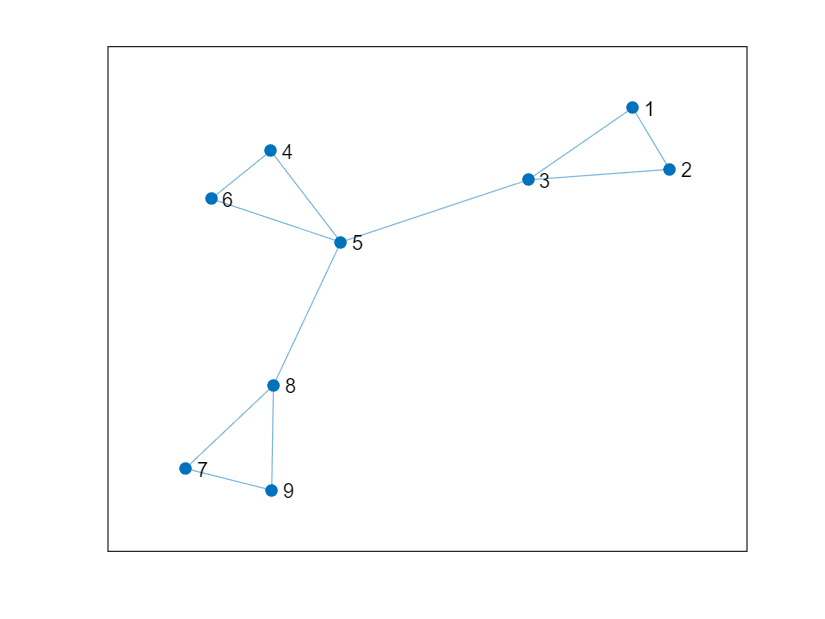


plot(G)



scomponents(A,[],0,[])

v = 2

label =      1     1     1


v = 6

label =      1     1     1     0     0     0     2     2     2


v = 3

label =      1     1     1     3     3     3     2     2     2



predecessor(A, 3)

ans = 9×1 logical array
   1
   1
   1
   0
   1
   0
   0
   0
   0


C = contract(A,[1 1 1 2 2 4 5 6 7])

b = graph(C)

b.plot()

function x = predecessor(G, v)
% Predecessors of a node in a graph
x = sparse(length(G), 1);
x(v) = 1; % Start BFS from v.
x = x | G * x;
end

 function scomponents(G,map,count,label)
 % Strongly connected components of a graph

 if count==0; map = 1:length(G); end % start recursion
 if isempty(G); return; end % end recursion

 v=1+ fix(rand * length(G)) % random pivot
 pred = predecessor(G,v);
 desc = predecessor(G',v);
 % Intersection of predecessors+descendants is a component.
 scc = pred & desc;
 count = count + 1;
 label(map(scc)) = count 

 % Recurse on subgraph of predecessors
 remain = xor(pred,scc);
 scomponents(G(remain,remain),map(remain),count,label);

 % Recurse on subgraph of descendants
 remain = xor(desc,scc);
 scomponents(G(remain,remain),map(remain),count,label);

 % Recurse on subgraph of remaining nodes
 remain = ~(pred | desc);
 scomponents(G(remain,remain),map(remain),count,label);
 end

function C = contract(G,labels)
% Contract nodes with the same label

n = length(G);
m = max(labels);
S = sparse(labels, 1:n, 1, m, n);
C = S * G * S';
end

